# Progetto 0

clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');

## 1. Joint 2 Identification

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.5;
ampiezza_portante=20;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=60;

Sommo i due segnali

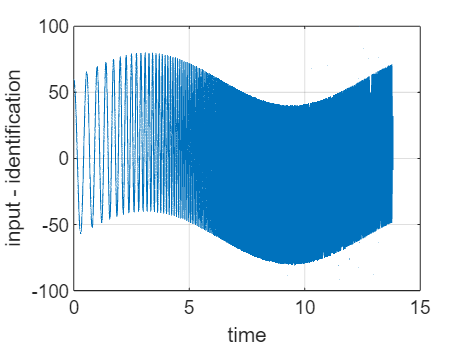

control_action=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

### 1.1 Simulazione sistema

I tratti con velocità vicina allo 0 hanno una dinamica chiaramente non lineare, l'approssimazione lineare nelle frequenze esplorare dal segnale eccitante in quei punti sarà scarsa.

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
k=50/(1/360*2*pi);
x=x0;
s=tf('s');
Ti=10;
PI=k*(1+1/(Ti*s));
controller1=Controller(st,PI,[-600 600]);
torque=zeros(length(control_action),2);
process_output_id2=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(1));
    [x,t(idx,1)]=cs.openloop([still_ca control_action(idx)]);
    process_output_id2(idx,:) = x;
    torque(idx,:) = [still_ca control_action(idx)];
end
toc

Elapsed time is 36.015080 seconds.


Joint 2

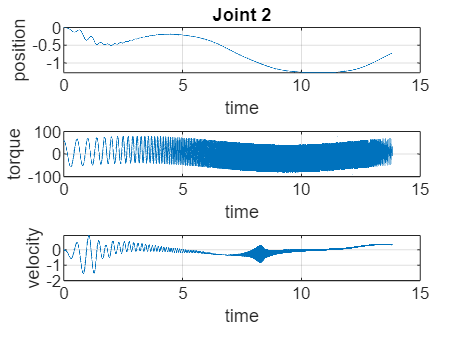

figure(1)
subplot(3,1,1)
plot(t,process_output_id2(:,2))
xlabel('time')
ylabel('position')
title('Joint 2')
grid on

subplot(3,1,2)
plot(t,torque(:,2))
xlabel('time')
ylabel('torque')
grid on

subplot(3,1,3)
plot(t,process_output_id2(:,4))
xlabel('time')
ylabel('velocity')
grid on

Joint 1

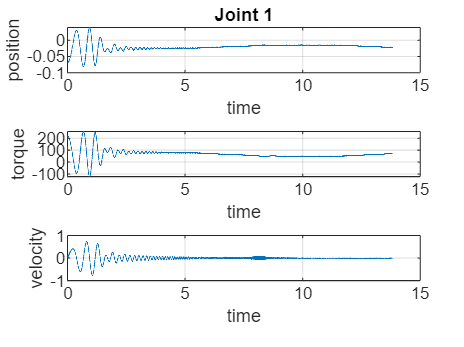

figure(2)
subplot(3,1,1)
plot(t,process_output_id2(:,1))
xlabel('time')
ylabel('position')
title('Joint 1')
grid on

subplot(3,1,2)
plot(t,torque(:,1))
xlabel('time')
ylabel('torque')
grid on

subplot(3,1,3)
plot(t,process_output_id2(:,3))
xlabel('time')
ylabel('velocity')
grid on

Nota: le frequenze in prossimità dei cambi di velocità sono stimate peggio (è opportuno che: 1) ripetere con segnali diversi 2) in validazione il signale sia diverso).

### 1.2 Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output_id2(:,4),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);
figure(3)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

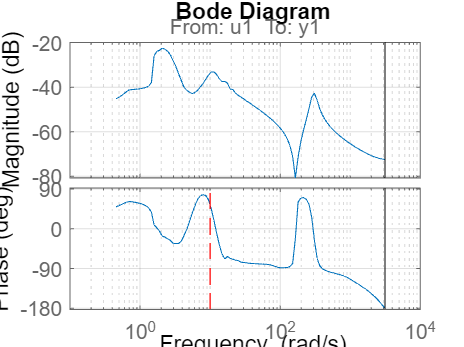

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### 1.3 Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=10;
wpeso1=pi/st;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_j2 = ssest(freq_resp_ident,7,opts);
modello_discreto_j2 = ssest(freq_resp_ident,7,'Ts',st,opts);
modello_continuo_tf_j2=tf(modello_continuo_j2)

modello_continuo_tf_j2 =
 
  From input "u1" to output "y1":
      0.5075 s^6 + 8.312 s^5 + 1.229e04 s^4 + 2.688e05 s^3 + 3.996e06 s^2 + 3.131e07 s + 2.073e07
  ---------------------------------------------------------------------------------------------------
  s^7 + 84.99 s^6 + 9.222e04 s^5 + 3.297e06 s^4 + 5.874e07 s^3 + 9.376e08 s^2 + 6.131e09 s + 5.375e10
 
Continuous-time transfer function.



save modello_j2 modello_continuo_tf_j2

### 1.4 Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo_j2,modello_discreto_j2, bode_opts)

visualizzo solo il range di frequenze di interesse

xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

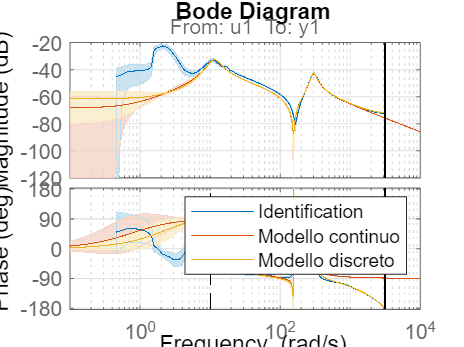

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')

### 1.5 Model validation

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.5;
ampiezza_portante=20;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w1/2/pi,t(end),w0/2/pi, 'logarithmic');
ampliezza_identificazione=60;

Sommo i due segnali

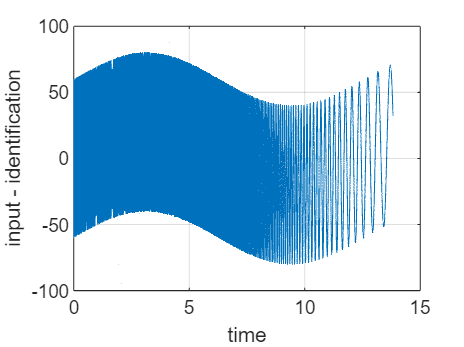

control_action_validation=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action_validation)
xlabel('time')
ylabel('input - identification')
grid on

#### 1.5.1 simulation

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
k=50/(1/360*2*pi);
x=x0;
s=tf('s');
Ti=10;
PI=k*(1+1/(Ti*s));

controller1=Controller(st,PI,[-600 600]);
torque=zeros(length(control_action),2);
process_output_id2=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(1));
    [x,t(idx,1)]=cs.openloop([still_ca control_action_validation(idx)]);
    process_output_id2(idx,:) = x;
    torque(idx,:) = [still_ca control_action_validation(idx)];
end
toc

Elapsed time is 35.264747 seconds.


#### 1.5.2 Validation

data=iddata(process_output_id2(:,4),torque(:,2),st)

data =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


omega_filter=5;
filter=s^2/(s+omega_filter)^2

filter =
 
        s^2
  ---------------
  s^2 + 10 s + 25
 
Continuous-time transfer function.



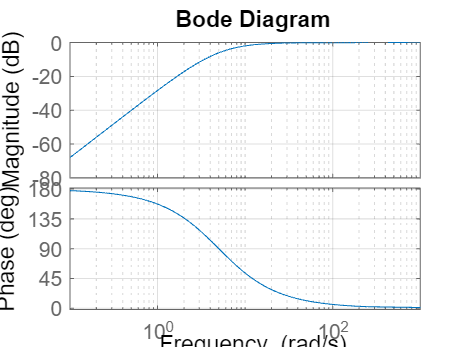

bode(filter)
grid on

filter_d=c2d(filter,st)

filter_d =
 
     z^2 - 2 z + 1
  -------------------
  z^2 - 1.99 z + 0.99
 
Sample time: 0.001 seconds
Discrete-time transfer function.



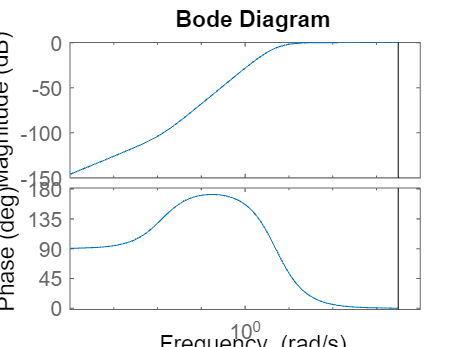

bode(filter_d)

data_filt=idfilt(data,filter)

data_filt =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


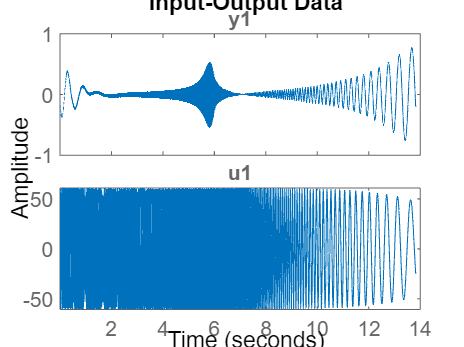

plot(data_filt)

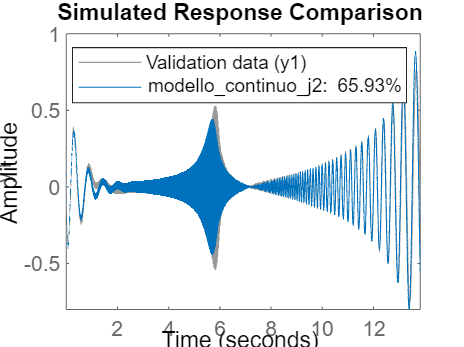

compare(data_filt,modello_continuo_j2)

clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');
load modello_j2.mat


## 2. Joint 1 Identification

### 2.1 Controller joint 2

figure
G = tf(modello_continuo_tf_j2);

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 100 rad/s)

wc=80;

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/20; % pulsazione azione integrale
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*G,wc));
C=Kp*Co

C =
 
  188.9 s + 755.8
  ---------------
      0.25 s
 
Continuous-time transfer function.



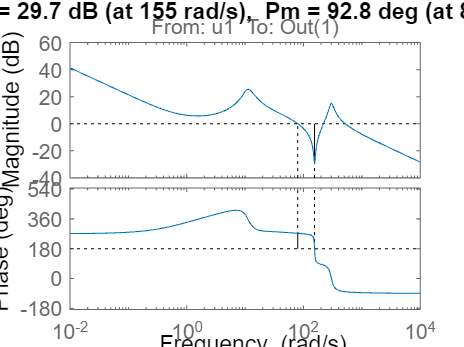

figure
margin(C*G)

### 2.2 Filtro notch

damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.94e+00 + 1.09e+01i     1.75e-01       1.11e+01         5.16e-01    
 -1.94e+00 - 1.09e+01i     1.75e-01       1.11e+01         5.16e-01    
 -4.09e+00 + 1.36e+01i     2.88e-01       1.42e+01         2.44e-01    
 -4.09e+00 - 1.36e+01i     2.88e-01       1.42e+01         2.44e-01    
 -2.42e+01                 1.00e+00       2.42e+01         4.13e-02    
 -2.44e+01 + 2.99e+02i     8.13e-02       3.00e+02         4.10e-02    
 -2.44e+01 - 2.99e+02i     8.13e-02       3.00e+02         4.10e-02    


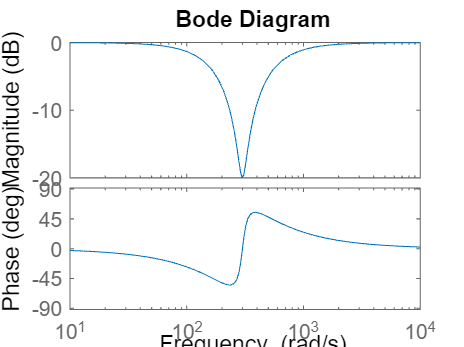


wn=300;
xci_z=0.08; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.8;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
bode(notch)

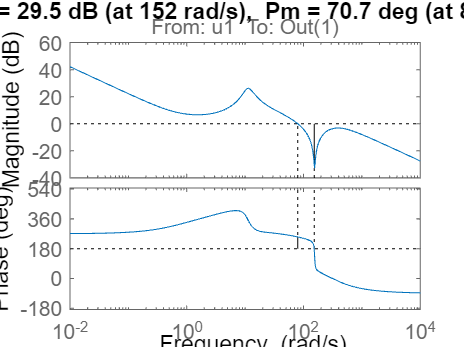


Kp=1/abs(freqresp(Co*G*notch,wc));
C=Kp*Co*notch;
figure
margin(C*G)


getPeakGain(feedback(1,C*G))

ans = 1.1943

### 2.3 Generazione Chirp

Costruzione segnale Chirp per primo giunto

omega_portante_j1=1;
ampiezza_portante_j1=20;
T_portante=2*pi/omega_portante_j1;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante_j1*sin(omega_portante_j1*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione_j1 = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione_j1=80;

Sommo i due segnali

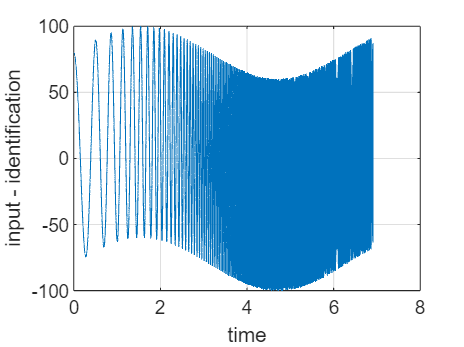

control_action_j1=portante + control_action_identificazione_j1*ampliezza_identificazione_j1;
figure
plot(t,control_action_j1)
xlabel('time')
ylabel('input - identification')
grid on

Identificazione giunto 1

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
x=x0;


controller1=Controller(st,C,1);
controller1.setUMax(600);
torque=zeros(length(control_action_j1),2);
process_output_id1=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(2));
    [x,t(idx,1)]=cs.openloop([control_action_j1(idx) still_ca]);
    process_output_id1(idx,:) = x;
    torque(idx,:) = [control_action_j1(idx) still_ca];
end
toc

Elapsed time is 17.415405 seconds.


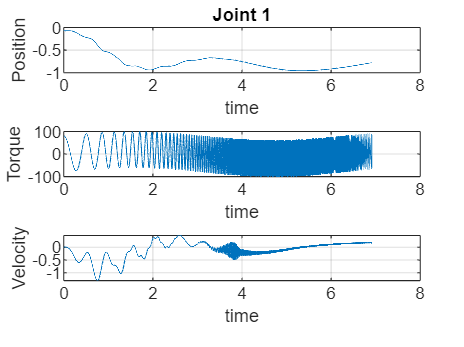

figure
subplot(3,1,1)
plot(t,process_output_id1(:,1))
xlabel('time')
ylabel('Position')
title('Joint 1')
grid on

subplot(3,1,2)
plot(t,torque(:,1))
xlabel('time')
ylabel('Torque')
grid on

subplot(3,1,3)
plot(t,process_output_id1(:,3))
xlabel('time')
ylabel('Velocity')
grid on

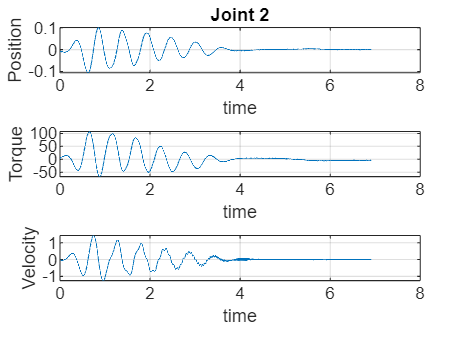

figure
subplot(3,1,1)
plot(t,process_output_id1(:,2))
xlabel('time')
ylabel('Position')
title('Joint 2')
grid on

subplot(3,1,2)
plot(t,torque(:,2))
xlabel('time')
ylabel('Torque')
grid on

subplot(3,1,3)
plot(t,process_output_id1(:,4))
xlabel('time')
ylabel('Velocity')
grid on

### 2.4 Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output_id1(:,3),control_action_j1,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident_j1 = spafdr(identification);
figure(3)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident_j1, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

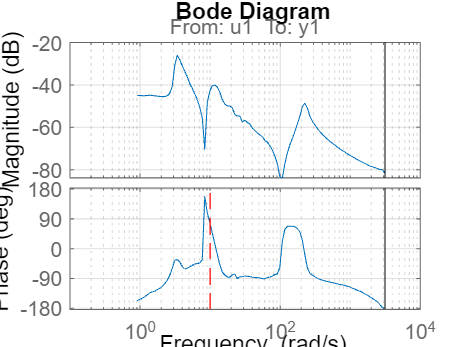

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### 2.5 Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident_j1.Frequency),1);
wpeso0=10;
wpeso1=1000;
peso(freq_resp_ident_j1.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident_j1.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_j1 = ssest(freq_resp_ident_j1,7,opts);
modello_discreto_j1 = ssest(freq_resp_ident_j1,7,'Ts',st,opts);
modello_continuo_tf_j1=tf(modello_continuo_j1)

modello_continuo_tf_j1 =
 
  From input "u1" to output "y1":
         0.1992 s^6 + 1.41 s^5 + 2137 s^4 + 5841 s^3 + 5.211e05 s^2 - 1.221e06 s + 2.958e07
  -------------------------------------------------------------------------------------------------
  s^7 + 51.55 s^6 + 4.987e04 s^5 + 5.149e05 s^4 + 1.549e07 s^3 + 7.526e07 s^2 + 9.994e08 s + 0.7987
 
Continuous-time transfer function.



save modello_j1 modello_continuo_tf_j1

### 2.6 Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident_j1, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo_j1,modello_discreto_j1, bode_opts)

visualizzo solo il range di frequenze di interesse

xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

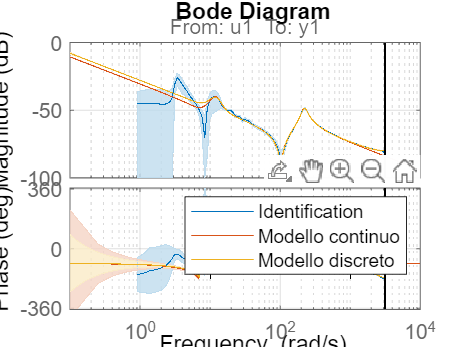

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')

### 2.7 Model validation

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.5;
ampiezza_portante=20;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w1/2/pi,t(end),w0/2/pi, 'logarithmic');
ampliezza_identificazione=80;

Sommo i due segnali

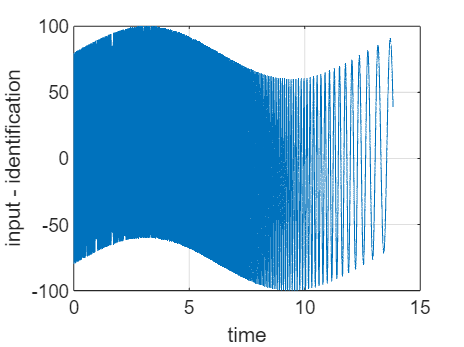

control_action_validation_j1=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action_validation_j1)
xlabel('time')
ylabel('input - identification')
grid on

#### 2.7.1 simulation

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
x=x0;

pi_d=c2d(C,st);
controller1=Controller(st,C,1);
controller1.setUMax(600);
torque=zeros(length(control_action_j1),2);
process_output_id1=[];
torque=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(2));
    [x,t(idx,1)]=cs.openloop([control_action_validation_j1(idx) still_ca]);
    process_output_id1(idx,:) = x;
    torque(idx,:) = [control_action_validation_j1(idx) still_ca];
end
toc

Elapsed time is 33.285584 seconds.


#### 2.7.2 Validation

data=iddata(process_output_id1(:,3),torque(:,1),st)

data =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


omega_filter=15;
filter=s^2/(s+omega_filter)^2

filter =
 
        s^2
  ----------------
  s^2 + 30 s + 225
 
Continuous-time transfer function.



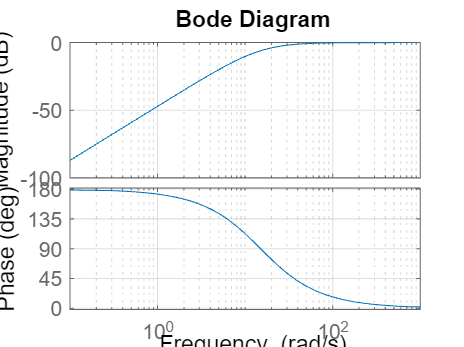

bode(filter)
grid on

filter_d=c2d(filter,st)

filter_d =
 
   z^2 - 2 z + 0.9999
  ---------------------
  z^2 - 1.97 z + 0.9704
 
Sample time: 0.001 seconds
Discrete-time transfer function.



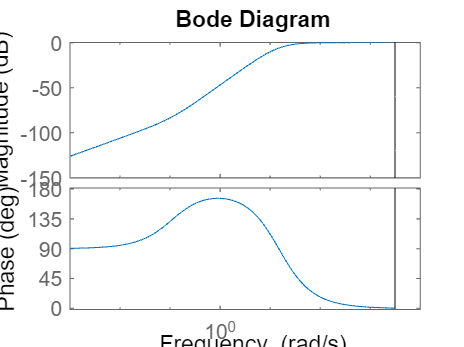

bode(filter_d)

data_filt=idfilt(data,filter)

data_filt =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


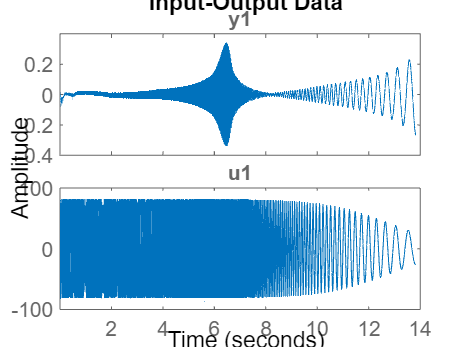

plot(data_filt)

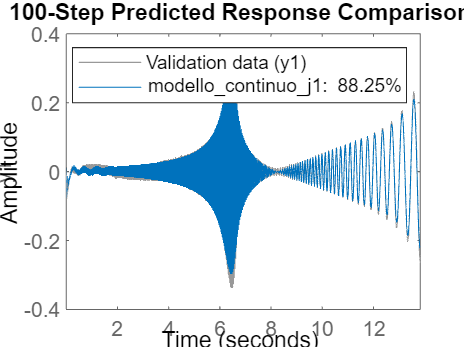

compare(data_filt,modello_continuo_j1)